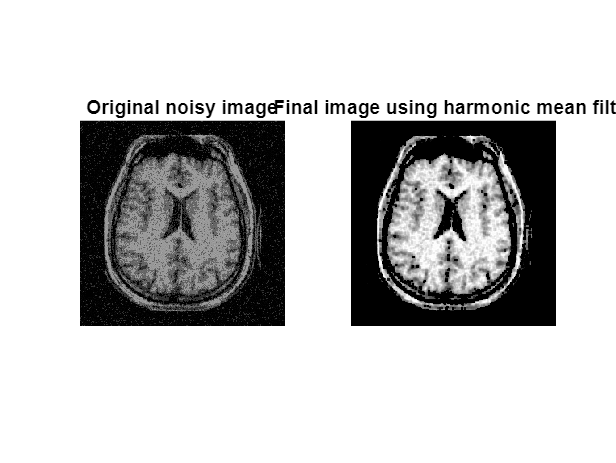

clc;clear;close all;
i=uigetfile('*.*');
I=imread(i);
J=rgb2gray(I);
subplot(1,2,1);
imshow(J);title("Original noisy image");
K=padarray(J,[1,1],1);
K=double(K);
[rows,columns]=size(K);
L=zeros(rows,columns);

for r=2:rows-1 
    for c=2:columns-1
        filt=[K(r,c),K(r-1,c),K(r+1,c),K(r,c-1),K(r,c+1),K(r-1,c-1),K(r-1,c+1),K(r+1,c-1),K(r+1,c+1)];
        s=sum(1./filt);
        x=9./s;
        L(r,c)=double(x);
    end    
end
subplot(1,2,2);
M=uint8(L);
imshow(M,[]);
title("Final image using harmonic mean filter");